# STATISTICAL MODELS: LAB 4

**Members**:

- Luca Franceschi (u199149)

- Marina Castellano (u188311)

- Paula Ceprián (u198630)

% path from MATLAB CURRENT FOLDER to files
dir_prefix = 'resampling/lab4/';

## FUNCTIONS

function corr = correlation_coeff(data)
    % Get shape of the data
    n = size(data, 1);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);

    % Compute correlation coefficient
    num = q * (ordered_data - mean(ordered_data, 1));
    denom1 = diag((ordered_data - mean(ordered_data, 1))' * (ordered_data - mean(ordered_data, 1)))';
    denom2 = q * q';
    
    corr = num ./ sqrt(denom1 .* denom2);
end

function corr = qq_plot(data)
    % Get shape of the data
    [n, dims] = size(data);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);
    
    figure;
    set(gcf,'position',[0,0,2000,1000]);

    corr = correlation_coeff(data);
    
    % Draw the corresponding QQ-Plots with regression line
    for i=1:dims
        % Create subplot
        subplot(ceil(sqrt(dims)),floor(sqrt(dims)), i);

        % Scatter plot and regression line in each axis
        scatter(q, ordered_data(:, i));
        hold on;
        b = [ones(n, 1) q']\ordered_data(:,i);
        ycalc = [ones(n, 1) q']*b;
        plot(q, ycalc);

        % Display correlation coefficient too
        y = (ordered_data(end,i)-ordered_data(1,i))*0.1 + ordered_data(1,i);
        text(q(end), y, ['\rho: ' num2str(corr(i))]);
        hold off;

        % Set title and labels for each axis
        title(['QQ-Plot for dim=' num2str(i)]);
        xlabel('Standard normal quantiles');
        ylabel(['Dim=' num2str(i) ' Quantiles']);
    end
end

% function corr = retrieve_qq_critical(table, n, alpha)
%     cols = [NaN 0.01 0.05 0.1]; % table is formatted this way to make it easier
%     col = ismember(cols, alpha);
%     if ~any(col)
%         error 'Invalid confidence level. Allowed ones are {0.01, 0.05, 0.1}'
%     end
% 
%     if any(ismember(table{:, 'n'}, n))
%         % disp('Entry exists');
%         corr = table{table{:, 'n'} == n, :}(col);
%     elseif n > 300
%         disp('Too large n. Will approximate to n=300');
%         corr = table{table{:, 'n'} == 300, :}(col);
%     else
%         % disp('Entry does not exist, performing linear interpolation');
%         lowerBound = table{table{:, 'n'} < n, :}(end,:);
%         upperBound = table{table{:, 'n'} > n, :}(1,:);
%         corr = linspace(lowerBound(col), upperBound(col), upperBound(1)-lowerBound(1));
%         corr = corr(n-lowerBound(1)+1);
%     end
% end

% function detect_outliers(data, alpha)
%     p = size(data, 2);
%     sample_mean = mean(data);
%     cov_matrix = cov(data);
% 
%     % Calculate Mahalanobis Distance for each observation
%     mahalanobis_dist = sqrt((data-sample_mean) / cov_matrix * (data-sample_mean)');
% 
%     % Chi-square distribution 
%     threshold = chi2inv(1-alpha, p); 
% 
%     outliers = find(mahalanobis_dist > threshold);
%     if any(outliers)
%         fprintf('The are outliers');
%     else
%         fprintf('The are no outliers.')
%     end
% end

% This function detects how many and deletes the outliers from the data
% function cleaned_data = clean_outliers(data, alpha)
%     p = size(data, 2);
%     sample_mean = mean(data);
%     cov_matrix = cov(data);
% 
%     mahalanobis_dist = sqrt(sum(((data - sample_mean) / cov_matrix) .* (data - sample_mean), 2));
%     threshold = chi2inv(1 - alpha, p);
%     outliers = mahalanobis_dist > threshold; 
%     num_outliers = sum(outliers); 
% 
%     if num_outliers > 0
%         fprintf('There are %d outliers.\n', num_outliers);
%     else
%         fprintf('There are no outliers.\n');
%     end
% 
%     cleaned_data = data(~outliers, :); % Keep only rows where outliers are false
% end

function iqr = myIQR(data)
    if ~isvector(data)
        error 'Input must be a vector';
    end

    % Sort the data in ascending order
    sorted = sort(data);

    n = size(data, 1);

    q1 = sorted(ceil(n/4));
    q3 = sorted(ceil(3*n/4));
    
    iqr = [q1, q3];
end

function detect_outliers(data)
    iqr = myIQR(data);
    iqr_range = iqr(2) - iqr(1);
    interval = [iqr(1) - iqr_range * 1.5, iqr(2) + iqr_range * 1.5];
    outliers = data < interval(1) | data > interval(2);
    
    if any(outliers)
        fprintf('The are outliers');
    else
        fprintf('The are no outliers.')
    end
end

function cleaned_data = clean_outliers(data)
    iqr = myIQR(data);
    iqr_range = iqr(2) - iqr(1);
    interval = [iqr(1) - iqr_range * 1.5, iqr(2) + iqr_range * 1.5];
    clean_data_idx = data >= interval(1) & data <= interval(2);
    cleaned_data = data(clean_data_idx);
end

function resample = boot_resample(X, B, dependency)
    % check input shape
    % dependency is a string that determines if there is any dependency
    %     between the rows of the data (if they have to be sampled by
    %     columns or the links should be broken).
    %     Options: 'dependent' or 'independent
    if ~ismatrix(X)
        error 'boot_resample: The input has unexpected shape'
    end

    [m, n] = size(X);

    if strcmp(dependency, 'independent')
        random_idxs = ceil(rand(m, n, B)*n);
        resample = random_idxs; % init for efficiency
        % sample row-wise differently
        for i=1:m
            resample(i,:,:) = reshape(X(i, random_idxs(i,:,:)), 1, n, B);
        end
    elseif strcmp(dependency, 'dependent')
        resample = reshape(X(:,ceil(rand(B, n)*n)), m, n, B);
    else
        error 'boot_resample: Input parameter 3 (dependency) not recognized'
    end
end

function [ci, corrected_ci] = boot_percentiles_ci(sample_est, resample_est, B, alpha)
    resample_est_ord = sort(resample_est);
    est_low = resample_est_ord(ceil((B+1)*alpha/2));
    est_high = resample_est_ord(ceil((B+1)*(1-alpha/2)));
    ci = [est_low, est_high];
    corrected_ci = [2*sample_est - est_high, 2*sample_est - est_low];
end

function bias = boot_bias(sample_est, resample_est)
    expected_est = mean(resample_est);
    bias = expected_est - sample_est;
end

function se = boot_standard_error(resample_est)
    se = std(resample_est);
end

function ci = boot_studentized_ci(sample_est, se, n, alpha)
    c = tinv(1-alpha/2, n-1);

    ci = [sample_est - c*se, sample_est + c*se];
end

function p = p_value(sample_est, resample_est, B, tails)
    resample_est_ord = sort(resample_est);
    if strcmp(tails, 'two-tail')
        count = sum(abs(resample_est_ord) >= abs(sample_est));
    elseif strcmp(tails, 'left-tail')
        count = sum(resample_est_ord <= sample_est);
    elseif strcmp(tails, 'right-tail')
        count = sum(resample_est_ord >= sample_est);
    else
        error 'p_value: Input parameter 4 (tails) not recognized'
    end
    p = (count + 1) / (B + 1);
end

function corr_coeff = my_corr(X)
    % Input X can be a matrix 2xn or 2xnxB
    % Output has the shape Bx1
    % Should work flawlessly (tested) for input shape 2xn or 2xnxB

    % check input shape
    if ismatrix(X)
        % if no B dimension, we append a singleton dimension so formulas
        % work the same (as if B was 1)
        [m, n] = size(X);
        X = reshape(X, m, n, 1);
    end
    if ndims(X) > 3
        error 'my_corr: The input has unexpected shape'
    end
    m = size(X,1);
    if m ~= 2
        error 'my_corr: The input should have two rows to compute the correlation'
    end
    % https://es.mathworks.com/matlabcentral/answers/15884-correlation-for-multi-dimensional-arrays#answer_21553
    % Compute correlations on second dimension
    % Remove means 
    az = bsxfun(@minus, X(1,:,:), mean(X(1,:,:), 2));
    bz = bsxfun(@minus, X(2,:,:), mean(X(2,:,:), 2));
    % Standard Pearson correlation coefficient formula
    a2 = az .^ 2;
    b2 = bz .^ 2;
    ab = az .* bz;
    corr_coeff = sum(ab, 2) ./ sqrt(sum(a2, 2) .* sum(b2, 2));
    corr_coeff = squeeze(corr_coeff);
end

% COMPUTE THE CRITICAL CORRELATION COEFFICIENT FOR B = 1000
% since it does not appear in the table
B_pr = 1e5;
N = 1e3;

corr = zeros(B_pr, 1);
for b=1:B_pr
    virtual_pop = normrnd(0, 1, N, 1);
    corr(b) = correlation_coeff(virtual_pop);
end

sorted_corr = sort(corr);

## PROBLEM 1

File *SM23_LabMarks.xlsx *shows the lab marks obtained by the 74 matriculated students in Statistical Models in course 2023-2024. Similarly to the present course, labs 1, 3 and 5 consisted on small exams, while labs 2, 4 and 6 consisted of deliverables. We with to use the data from those 74 students as a random sample to make inferences about the continuous evaluation method that we are using.

More specifically, we wish to assess whether the tests are more difficult than the deliverables, for which we wish to make inferences about the following parameter: 

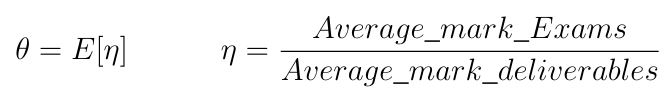

where $E\left\lbrack \right\rbrack$ stands for the expected value. In other words, for each student we are interested in the ratio between his/her average marks on the exams and his/her average marks on the deliverables, which we call $\eta$, and we set the expected value of these ratios as the parameter of the population to be analysed to answer our research question. We will use $\alpha =0\ldotp 05$ as the significance level.

**a) State the null and alternative hypotheses for this problem, including the mathematical formulation in terms of the requested parameter. **

$\begin{cases}
      H_{0}: \theta = 1\\
      H_{A}: \theta < 1\\
\end{cases}$ or equivalently $\begin{cases}
      H_{0}: \theta - 1 = 0\\
      H_{A}: \theta - 1 < 0\\
\end{cases}$ where $\theta$ is the expected population value of the ratio between average exam grades and average deliverable grades.

**b) Define a suitable statistic to make inferences about the parameter of interest. Compute this statistic on the provided samples and analyse the obtained values looking for any outliers or invalid data. Be careful with the assumptions that you use (since we expect to use bootstrap in this lab there is no need for normality); justify very well the reasons that allow the exclusion of any data sample in case you decide that this is needed.**

A suitable statistic for this task is the sample mean. The assumptions needed are the following ones:

- The measurements must be **independently and identically distributed**. That is, student A grades are independent of any other student B.

Since we are using only the averages to compute the needed statistic we will only check if there are outliers in the averages itself, not all its components, using QQ-plots.

% Importing data table for the problem
filename = strcat(dir_prefix, 'SM23_LabMarks.xlsx');
raw = readtable(filename);

% Importing critical values for normality assessment
% filename = strcat(dir_prefix, 'qq_plots_critical.csv');
% critical_values = readtable(filename);
alpha = 0.05;
B = 1e3;

deliverable_grades = raw{:,[1 3 5]};
exams_grades = raw{:,[2 4 6]};

deliverables_mean = mean(deliverable_grades, 2, 'omitnan');
exams_mean = mean(exams_grades, 2, 'omitnan');

First of all we will start with the deliverables mean. We will analyze its QQ-plot and we will try to detect outliers.

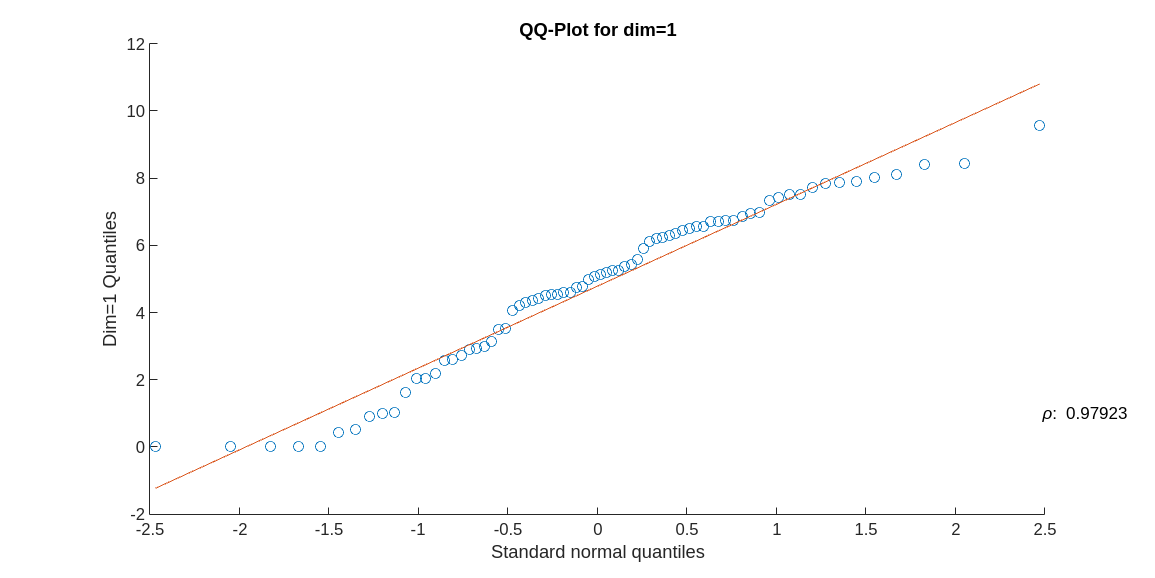

qq_plot(deliverables_mean);

critical_corr = sorted_corr(ceil(B*alpha));
critical_corr

critical_corr = 0.9969

detect_outliers(deliverables_mean);

The are no outliers.

From what we can see in the above QQ-plot, the **deliverables mean** **does not follow a normal distribution** since the correlation value is smaller than the critical value for the correlation. However there are **no outliers**.

We will do the same with the exams mean.

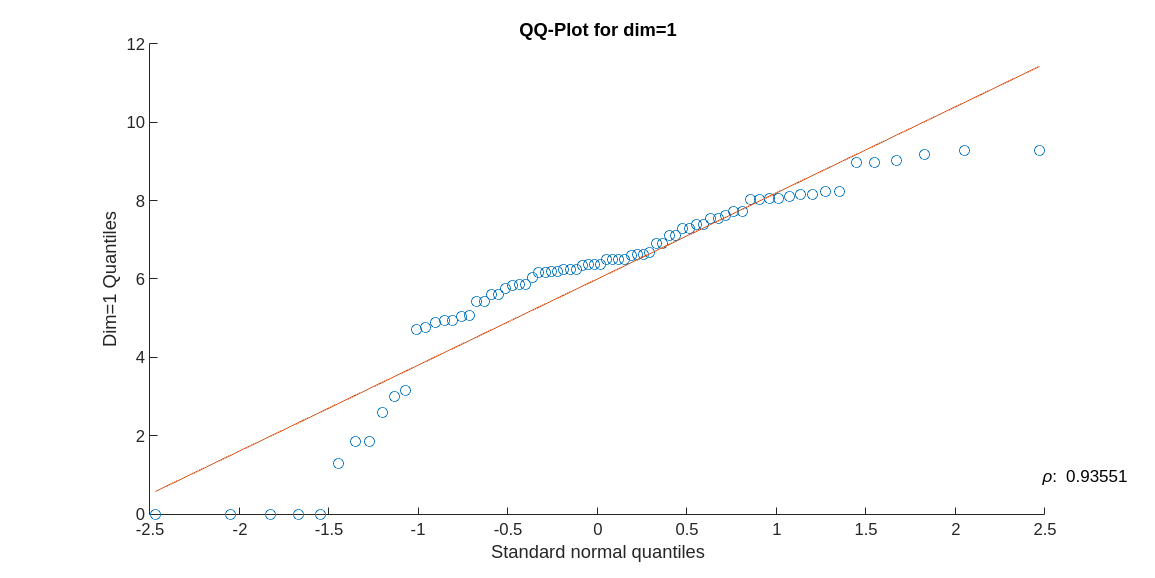

corr = qq_plot(exams_mean);

corr

corr = 0.9355

detect_outliers(exams_mean);

The are outliers

From what we can see in the above QQ-plot, the **tests mean** **does not follow a normal distribution** since the correlation value is smaller than the critical value for the correlation. However there are **no outliers**.

Since there is no need for normality we are not taking into account the (bad) correlation value of the means of both means. We are not detecting any outliers in the averaged data. Maybe in the non-averaged data (labs separately) there are some outliers but we are only taking into account the outliers in the denominator of our needed statistic, that is, the average of labs. The same happens with test means, the normality assumption would not be reached if needed, however we **cannot detect outliers**.

We conclude that there is **no need to exclude any data sample in this step**.

**c) Use the sample values computed in (b) to assess whether η is normally distributed.**

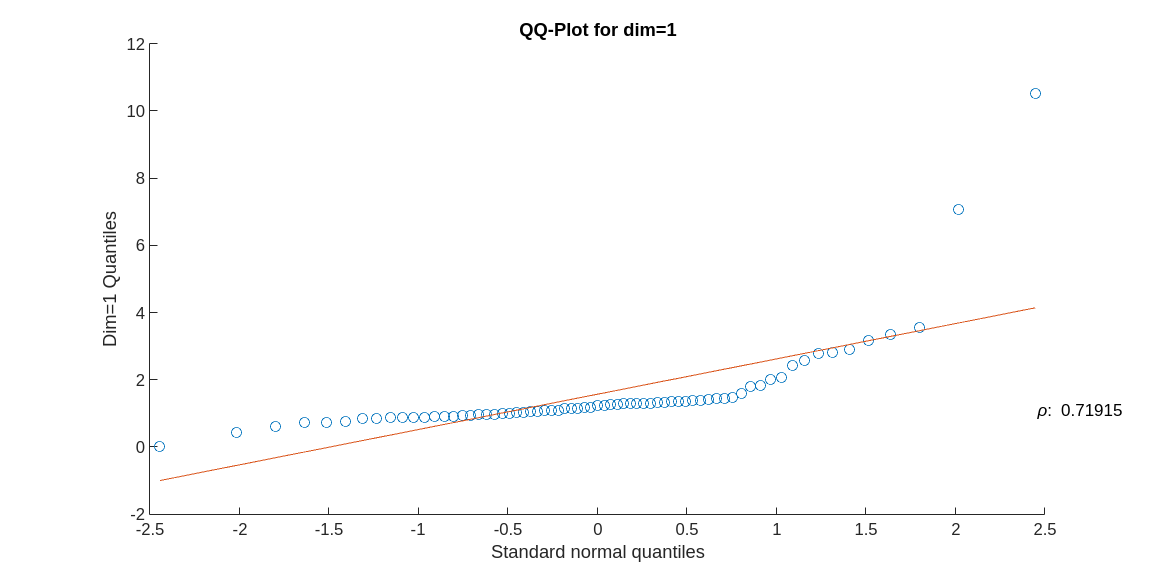

eta = exams_mean ./ deliverables_mean;
eta_clean = eta(~isnan(eta) & ~isinf(eta)); % remove problematic entries

qq_plot(eta_clean);

From what we can see in the above plot the correlation is quite bad (below critical threshold) and we can also see **a couple of outliers**, however we will need to further analyze those to be sure of removing them. We will analyze also the histograms of values.

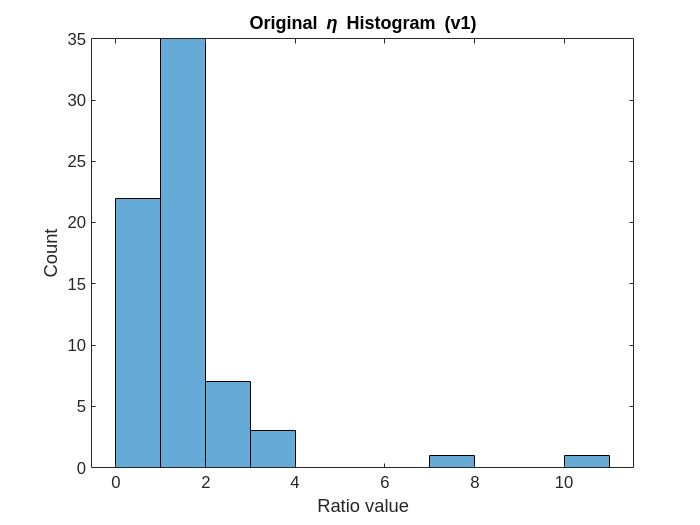

figure;
histogram(eta_clean);
title('Original \eta Histogram (v1)');
xlabel('Ratio value');
ylabel('Count');

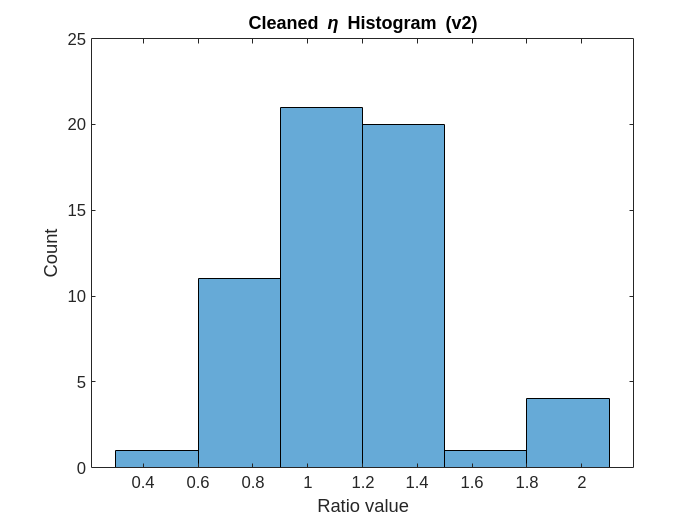

eta_clean = clean_outliers(eta_clean);
figure;
histogram(eta_clean);
title('Cleaned \eta Histogram (v2)');
xlabel('Ratio value');
ylabel('Count');

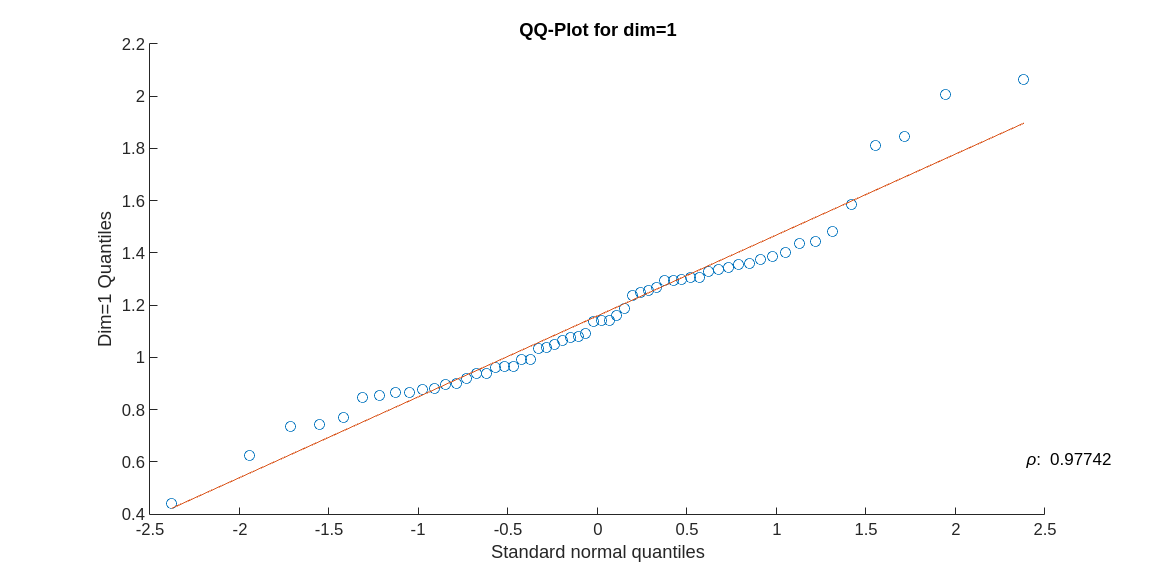

qq_plot(eta_clean);

critical_corr = sorted_corr(ceil(B*alpha));
critical_corr

critical_corr = 0.9969

There are two histograms because we have removed the outliers using the 1.5IQR rules. The last histogram shows the cleaned data.

We can see that there were multiple outliers (**excluding NaN and **$\textbf{Inf}$** data**). After removing them we can see that the data is **still not normal**, however we can assure that there are no outliers in the data. Normality should not be a problem since, as stated in problem 1b, there is no need for normality assumption in bootstrap.

**d) Theory suggests that, given the relatively large number of samples, the statistic that you selected in (b) should be normally distributed, regardless of your answer in (c) (Reflect about this and, if you find that it is not the case, then you have most likely chosen a wrong statistic in (b)). Use resampling to confirm whether this holds.**

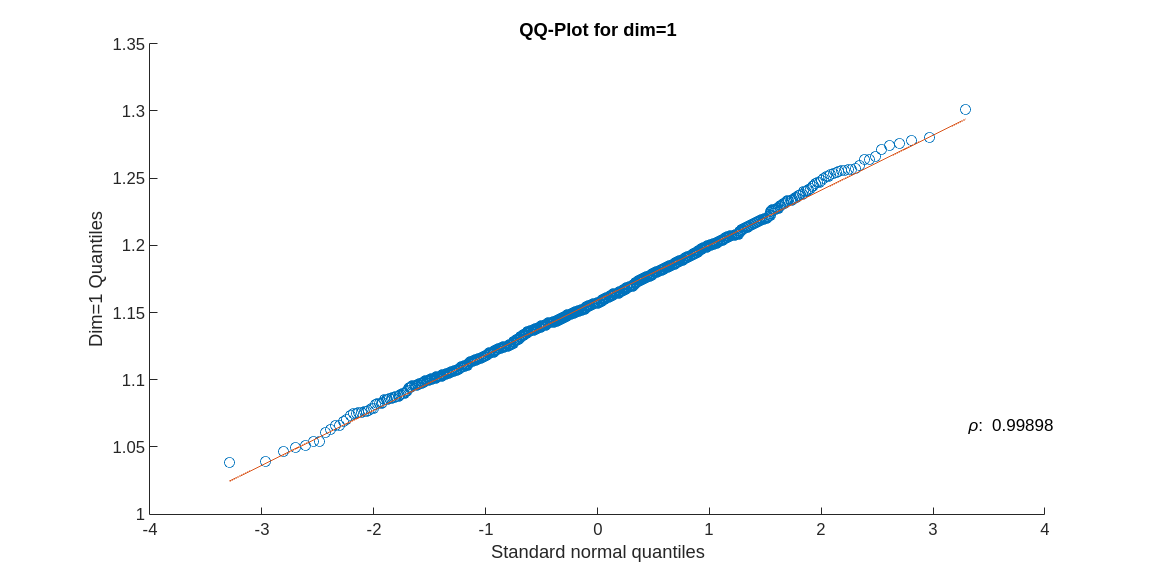

B = 1e3; % max table value so we do not need further approximations

resample = boot_resample(eta_clean', B, 'independent');
resample_est = squeeze(mean(resample, 2));

figure;
qq_plot(resample_est);

critical_corr = sorted_corr(ceil(B*alpha));
critical_corr

critical_corr = 0.9969

As expected, we can confirm that after the bootstrap resamples, **the statistic **$\mathbf{\eta}$** is normally distributed**. We can see that the QQ-plot follows a straight line and the correlation coefficient is larger than its critical counterpart for a given resample count and confidence level.

Conclusion: $\eta$ (our statistic) is normally distributed.

We believe that we have chosen the correct statistic because we can see that the QQ-plot shows a normally distributed resample. We also tried to test normality without removing the outliers and that showed that it was not normal. We think this is a good **hint that outliers have to be removed before computing our statistic**.

**e) Construct an adequate confidence interval for the parameter of interest, in such a way that you can use it to answer our research question. Provide the answer and a clear justification for it.**

sample_est = mean(eta_clean);

[ci, corrected_ci] = boot_percentiles_ci(sample_est, resample_est, B, alpha);
ci

ci =     1.0825    1.2466


corrected_ci

corrected_ci =     1.0713    1.2354


bias = boot_bias(sample_est, resample_est);
bias

bias = 2.5209e-04

We can see that the **confidence interval does not contain 1**, which means that we **can reject our null hypothesis** based on the confidence interval. Furthermore we have also computed the corrected confidence intervals in case the bias was high, which for the sample mean statistic should not be the case, since for a high number of resamples bias goes to 0. For B = 1000 our bias is shown above, which is not quite high, but still near zero. This is why both confidence intervals are very similar.

As we have concluded that $\eta$ follows a normal distribution, we can also compute the studentized confidence interval based on the standard error and bias of our statistic. We should recall that in this case they should be approximately equal (equal for large N).

se = boot_standard_error(resample_est);
ci = boot_studentized_ci(sample_est, se, B, alpha);
ci

ci =     1.0785    1.2394


As we theoretically expected, and as shown above, **the two methods for computing confidence intervals mostly agree**. With higher B values it should only get better.

**f) Use resampling to test the hypotheses in (a) directly and provide the obtained p-value; compare the result to the one obtained in (e).**

As we have stated in the exercise 1a, our hypothesis are the following:$\begin{cases}
      H_{0}: \theta - 1 = 0\\
      H_{A}: \theta - 1 < 0\\
\end{cases}$ . As in this exercise we are asked to test the hypothesis using bootstrap we need to, before resampling the data, **be under the null hypothesis**. In this case, as shown, we have to subtract one to our estimator $\theta$.

sample_est = mean(eta_clean) - 1; % to be under H0 we subtract one to each array position

resample = boot_resample(eta_clean', B, 'independent');
resample_est = squeeze(mean(resample, 2));
p = p_value(sample_est, resample_est, B, 'left-tail');
p

p = 9.9900e-04

Since the p value is smaller than the confidence level of $100\left(1-\alpha \right)%=95%$(where $\alpha =0\ldotp 05$) we can **reject the null hypothesis**, that is, **the difficulty of the tests is more difficult than the deliverables one**. This is compatible with the confidence interval results, where we also rejected the null hypothesis.

## PROBLEM 2

Using the same data used in Problem 1, we wish to address now a different question: are the exam and deliverable marks of students independent? In other words is there a clear relation between the (average) exam and deliverable marks obtained by each student, or they are simply independent because exams and deliverables are so different ways of assessing students?

Again, we will use $\alpha =0\ldotp 05$ as the significance level, and now the parameter of interest will be the correlation coefficient between the average-exam and average-lab marks.

**a) State the null and alternative hypotheses for this problem, including the mathematical formulation in terms of the requested parameter.**

$\begin{cases}
      H_{0}: \rho_{TD} = 0\\
      H_{A}: \rho_{TD} \neq 0\\
\end{cases}$ , where ${\rho \;}_{\textrm{TD}}$ is the population correlation coefficient between average test ($T$) grades and average deliverable ($D$) grades.

**b) Using the sample correlation as your statistic, compute its values using only the samples that you decided to be valid in Problem 1(b). Use resampling to assess whether the chosen statistic follow a normal distribution.**

DISCLAIMER: We would have preferred to automate this process of finding the outlier and problematic data indices. Since the outlier removal function changes the size of the cleaned data, it becomes very challenging for us to keep track of which indices are removed at each step. This is why we obtained the indices by inspecting the data manually rather than creating an automated algorithm. For a larger dataset it would have not been feasible, but luckily for this concrete problem it was quite fast.

alpha = 0.05;
B = 1e3;

outliers = [1 2 3 4 12 14 15];  % from inspecting the data manually

X = [deliverables_mean exams_mean];
X(outliers,:) = NaN;
X = X(~isnan(X(:,1)),:);

sample_est = my_corr(X');
sample_est
resamples_indep = boot_resample(X', B, 'independent');

sample_est = 0.5889

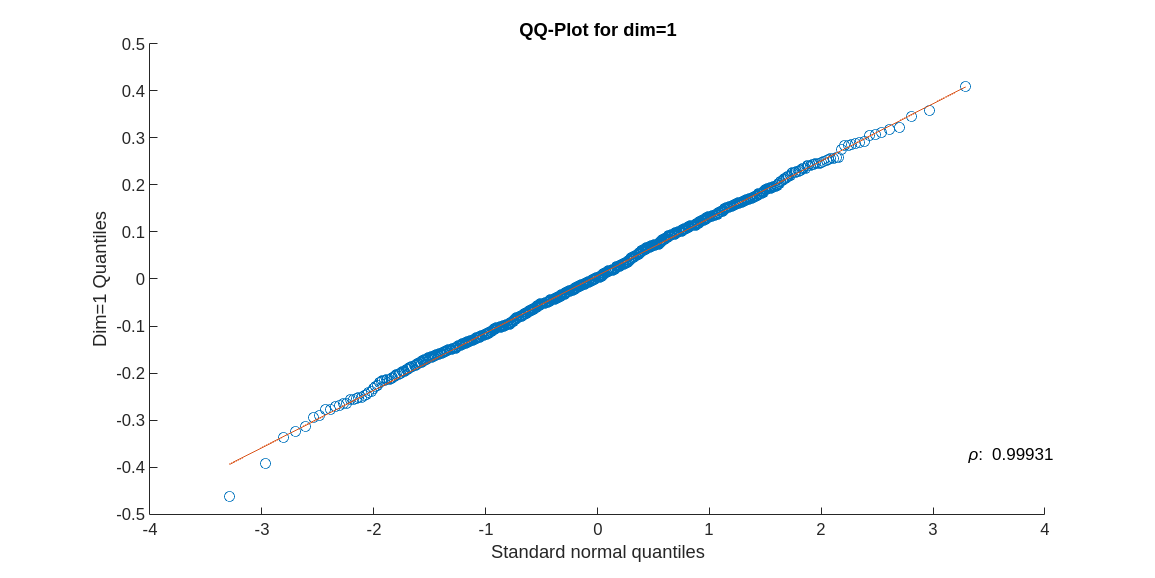

resample_est = my_corr(resamples_indep);
qq_plot(resample_est);
critical_corr = sorted_corr(ceil(B*alpha));

critical_corr

critical_corr = 0.9969

As the heading is asking for the correlation statistic we know that we have to **resample our data in order to fulfill the null hypothesis** (in this case, the deliverable grades are independent from test grades for each student). Which means, as stated in the null hypothesis, the correlation coefficient of both variables is zero. To fulfill that we must do the resamples with the data having correlation zero, **treating it as independent**. The plot that we obtain shows **normality of the resampled estimates** (the data follows a straight line and the correlation coefficient is greater than its critical threshold).

**c) Construct an adequate confidence interval for the parameter of interest, in such a way that you can use it to answer our research question. Provide the answer and a clear justification for it.**

resamples_dep = boot_resample(X', B, 'dependent');
resample_est = my_corr(resamples_dep);
[~, corrected_ci] = boot_percentiles_ci(sample_est, resample_est, B, alpha);
corrected_ci

corrected_ci =     0.4447    0.8045


On the other hand, theoretically, if we treat the sample independently when we want to construct the confidence interval, it will for sure contain zero (it will be centered or close to zero), which means that **we would never be able to reject the null hypothesis**. This is why we are **treating the samples as dependent**, since otherwise zero would be contained in the confidence interval regardless of the data.

Since we are asked to compute the 'adequate' confidence interval, we are only displaying the corrected percentiles confidence interval. We can see that 

$0 \notin \text{corrected\_ci}$, thus we can say with 95% confidence that **the average test (T) grades and average deliverable (D) grades are not independent** (rejecting the null hypothesis). In this case we can see that there is a **positive correlation** since the interval is strictly above 0, however we could also reject the null hypothesis if the interval was strictly below 0.

In other words, if we have a positive correlation it means that if the deliverable grades are high, the test grades are probably also high. The same happens to the opposite, if the correlation is negative it means that if the deliverable grades are high, the test grades are probably low. **In both cases we could reject the null hypothesis**.

**d) Use resampling to test the hypotheses in (a) directly and provide the obtained p-value; compare the result to the one obtained in (c).**

resample_est = my_corr(resamples_indep);
p = p_value(sample_est, resample_est, B, 'two-tail');
p

p = 9.9900e-04

As discussed in 2b, we need to be **under the null hypothesis** to be able to calculate the p-value as we want to test the hypothesis. This is why we are using again the **independent resamples** of 2b and not the ones of 2c.

We obtain a p-value that is smaller than $\alpha$, which means that we can **reject the null hypothesis** in favor of the alternative. Comparing the results with the ones obtained in 2c, they **arrive to the same conclusion** since $0 \notin \text{corrected\_ci}$.

From this evidence, we are able to **reject the null hypothesis**, hence we can say that **test grades and deliverable grades** **are not independent**. In other words, **both grades are correlated**.

## PROBLEM 3

To design clothing, a company selling excercise clothing has collected data on then physical characteristics of customers. File *SM_Lab_4_WeightsRunners.xlsx* provides the weights (kg) for a random sample of 25 male runners. Since products target the average male you are interested in seeing how much the subjects in your sample vary from the average weight.

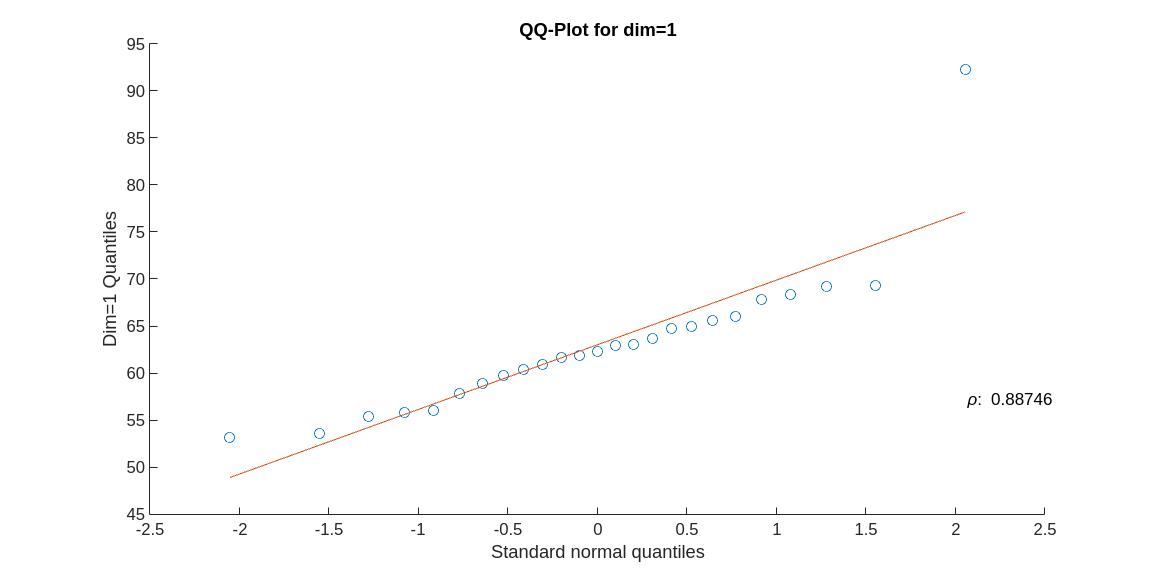

critical_corr = 0.9969

% Importing data table for the problem
filename = strcat(dir_prefix, 'SM_Lab_4_WeightsRunners.xlsx');
raw = readtable(filename);
X = raw{:,:};

qq_plot(X);
critical_corr = sorted_corr(ceil(B*alpha));
critical_corr

Firstly we want to inspect the data. That is why we wanted to visualize the data using QQ-plots to visually check if there are any apparent outliers. Visually we can see that there is an outlier (weight of 92.3kg). However when we use the mahalanobis distance to see if statistically it is an outlier, it is not. Even if it was an outlier we think that we should consider it as a valid sample since we are analyzing the variance of weights. If we were to remove it, we would defeat the purpose of the exercise to see how much the subjects in our sample vary from the average weight.

**a) Calculate the sample standard deviation** $\mathbf{\hat{\sigma}}$** for these weights and find the bias of **$\mathbf{\hat{\sigma}}$**.**

To compute the sample standard deviation $\hat{\sigma}$ without bias we just need to use the already done function in matlab, which divides by (n-1). This function returns an unbiased standard deviation.

To compute the bias of these $\hat{\sigma}$, we need to have the standard deviation normalizing by n and not by (n-1). This will return a biased standard deviation. Finally, to see the amount of bias, we need to do the difference between the unbiased and biased sample standard deviations:

sample_est = std(X) % normalized by N-1

As shown above, we have a quite small positive bias.

B = 1e3;

sample_est = 7.7060

resample = boot_resample(X', B, 'independent');
resample_est = squeeze(std(resample));

bias = boot_bias(sample_est, resample_est);
bias

**b) Use bootstrapping to find the bootstrap standard error for **$\mathbf{\hat{\sigma}}$**.**

se = boot_standard_error(resample_est);

bias = -0.5685

se

**c) Make a histogram of the bootstrap replications of **$\mathbf{\hat{\sigma}}$** from (b). Inspect the data to try assessing why do we obtain such a strange histogram.**

figure;

se = 2.2634

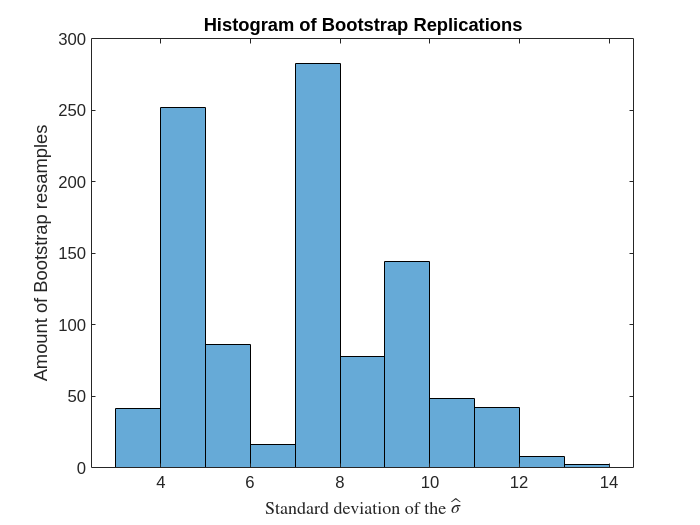

histogram(resample_est);
title('Histogram of Bootstrap Replications');
xlabel('Standard deviation of the $\hat{\sigma}$', Interpreter='latex');
ylabel('Amount of Bootstrap resamples');
qq_plot(resample_est);
critical_corr = sorted_corr(ceil(B*alpha));

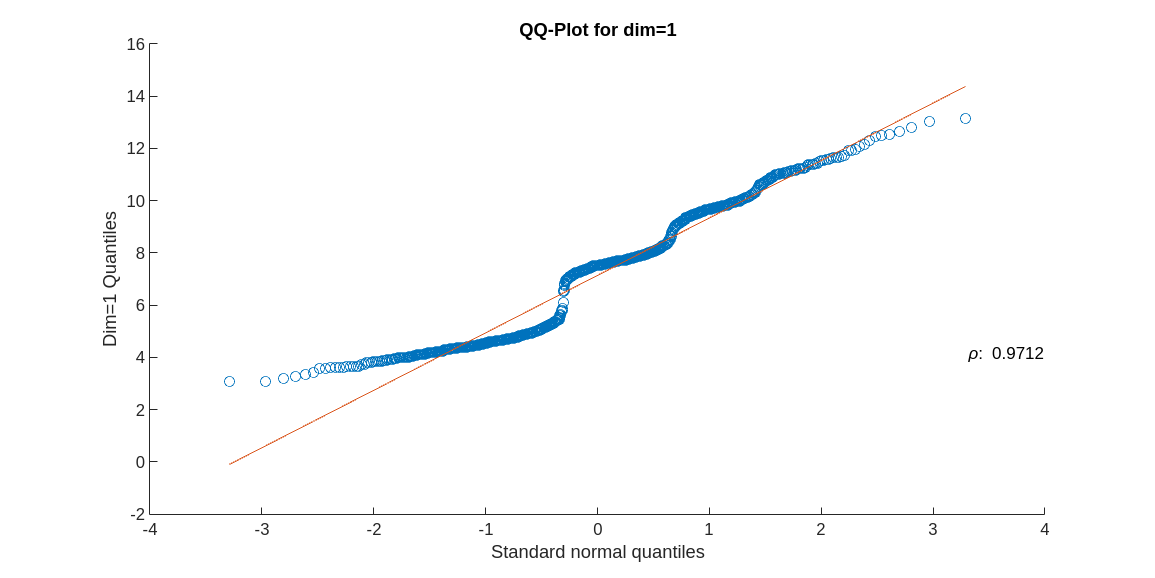

critical_corr = 0.9969

critical_corr

The histogram of the replicates shows a distribution of the standard deviations of B = 1000 bootstrap resamples, which is slightly skewed with most resamples at the lower end. This strange histogram can happen due to some reasons in the bootstrap process, **particularly if there are outliers** (the 92.3kg runner might be considered one) in the data **or if we are in front of a non-normal distribution**, which cause large variability in variance estimates across resamples.

This might happen due to the **small original sample size**: having only the weights of 25 males implies that in such a large number of bootstrap resamples such as 1000 we can have lots of repetitions of the weights. If, concretely, a high proportion of male have a similar weight in the original sample of size 25, with 1000 resamples this proportion will be even bigger. This is also the reason why this histogram **seems also multimodal**, since the most popular weights might appear multiple times in the same resamples, thus making these peaks. That is, in fact, that if the distribution of the original sample is skewed (not normally distributed), the bootstrap resamples may inherit this skewness for a small sample size as ours.

**d) Suggest a way to improve the analysis so that you can compute a confidence interval using bootstrapping. Clearly justify why your proposal is adequate.**

A possible improvement would be to **remove the outlier that we have discussed in the beginning** and in 3a. By removing it **we could possible achieve a normal distribution in the data**, which we could then use to compute the percentiles and even the studentized.

If the data was very heavy in its right-tail we could also **try to do a logarithmic transformation** for the data to be more normal. After that we could compute the confidence interval and rescale it using exponentiation. Source: (B. Efron & R.J. Tibshirani: An introduction to the bootstrap, Chapman & Hall, 1993, Chapter 13.3)

**e) Implement the solution proposed in (d) and compute a 95% confidence interval for **$\mathbf{\hat{\sigma}}$**. Clearly indicate what method you choose to compute the interval.**

X = clean_outliers(X);

sample_est = std(X)
resample = boot_resample(X', B, 'independent');
resample_est = squeeze(std(resample));

sample_est = 4.8078

bias = boot_bias(sample_est, resample_est);
bias
se = boot_standard_error(resample_est);
se

bias = -0.0929

figure;
histogram(resample_est);

se = 0.5281

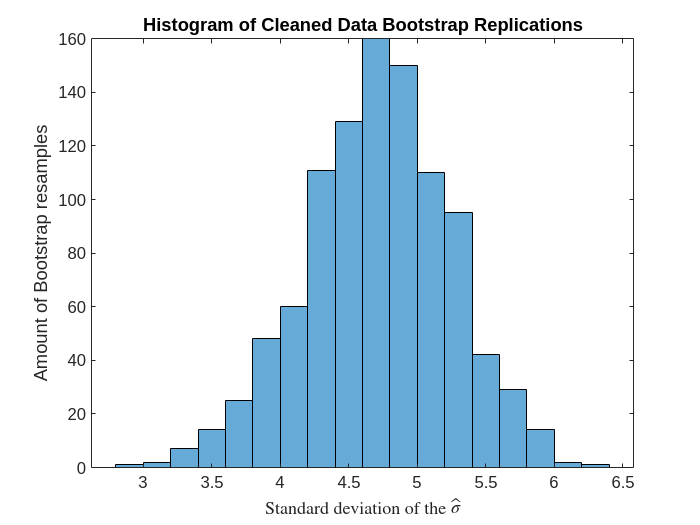

title('Histogram of Cleaned Data Bootstrap Replications');
xlabel('Standard deviation of the $\hat{\sigma}$', Interpreter='latex');
ylabel('Amount of Bootstrap resamples');
qq_plot(resample_est);
critical_corr = sorted_corr(ceil(B*alpha));

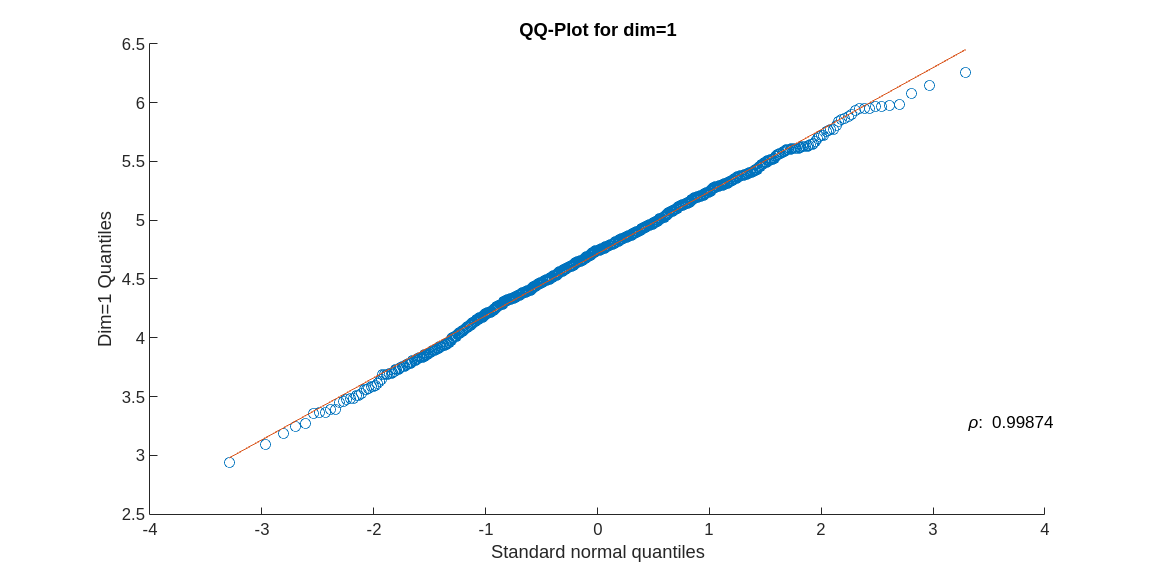

critical_corr

% percentiles method on the data
[ci, corrected_ci] = boot_percentiles_ci(sample_est, resample_est, B, alpha);

critical_corr = 0.9969

ci
corrected_ci
% studentized method on the data

ci =     3.6297    5.6918


ci = boot_studentized_ci(sample_est, se, B, alpha);

corrected_ci =     3.9238    5.9858


ci

ci =     3.7714    5.8441


We have used the **percentiles** (both corrected and non-corrected) method and the **studentized** one to compute the confidence intervals. The percentiles method should be very accurate even if the data was not normal, and since the distribution can be considered normal the studentized intervals are also very valid. For large resample count B they should agree. We can see that **both methods are very consistent in the upper and lower bounds**.